clear; close all; clc; % initializes environment

# 正射影ベクトルの長さの分散の楕円による幾何学的解釈

## 本章の目的

これまでは，正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$や$S=\left(u\prime ,\mathit{Du}\prime \right)$を三次元空間の関数としてとらえてその幾何学的解釈を解説してきました．この解釈ではデータ空間上の任意の方向を示すベクトル$u$や$u\prime$が単位ベクトル（$\left\|u\right\|=\left\|u\prime \right\|=1$）であることを幾何学的解釈に取り入れられることから，分散$S=\left(u,\mathit{Vu}\right)$や$S=\left(u\prime ,\mathit{Du}\prime \right)$の定義をより正確に反映できる解釈であると考えています．一方で，$\mathrm{PCA}$の幾何学的解釈として，楕円を用いた解説が広く用いられています．

本章では，楕円を用いたPCAの幾何学的解釈を紹介します．

## データの準備

### データの読み込み

引き続き，「米国３２９都市における生活満足度」のデータセットを用います．また，「健康」と「芸術」に関する指標を用いて，変数とする二変量データとして解説していきます．さらに，説明を簡単にするために，平均値が０，標準偏差が１になるように正規化しておきます．

load cities.mat;
scores_health_norm = normalize(ratings(:, 3)); % extracts scores on healt (the 3rd  column) and normalizes it
scores_arts_norm = normalize(ratings(:, 7)); % extracts scores on arts (the 7th column) and normalizes it

### データ行列の作成

説明のため，データ行列$X$を定義します．各行が「健康」および「芸術」に関する正規化された評価値に対応し，各列が観測に対応します．

X = [scores_health_norm scores_arts_norm]'

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

データ行列$X$の$i$番目の観測を$x^{\left(i\right)} =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1^{\left(\mathrm{i}\right)} \\
{\mathrm{x}}_2^{\left(\mathrm{i}\right)} 
\end{array}\right\rbrack$と表します．ここで，${\mathrm{x}}_1^{\left(\mathrm{i}\right)}$および${\mathrm{x}}_2^{\left(\mathrm{i}\right)}$はそれぞれデータ行列$X$の$i$番目の観測における一番目の変数（「健康」）と二番目の変数（「芸術」）の標準化された評価値です．

### 分散共分散行列

データ行列$X$の分散共分散行列$V$は

V = cov(X',1)

V =     0.9970    0.8632
    0.8632    0.9970


となります．

### 分散共分散行列$V$の固有ベクトルおよび固有値

eig()関数を用いて以下のように求めることができました．

[Q,D] = eig(V)

Q =     0.7071   -0.7071
   -0.7071   -0.7071


D =     0.1338         0
         0    1.8601


ここで，行列$Q$の各列が分散共分散行列$V$の固有ベクトルです．また，行列$D$は対角成分が固有値となる対角行列です．対角成分が左上から降順に並ぶように並び替えます．

[d,ind] = sort(diag(D),'descend');
D = diag(d)

D =     1.8601         0
         0    0.1338


固有ベクトルも対応するように，$Q$の列を左側から順次並べ替えていきます．

Q = Q(:,ind)

Q =    -0.7071    0.7071
   -0.7071   -0.7071


### pca()関数を用いた主成分分析

pca()関数を用いてデータ行列の主成分係数と主成分スコアを求めます．

[coefs,scores] = pca(X','Algorithm','eig')

coefs =     0.7071   -0.7071
    0.7071    0.7071


scores =    -0.9971    0.3406
    0.6991    0.0360
   -0.8441   -0.0436
    0.4020    0.0562
    0.6753   -0.2655
   -0.8138   -0.0443
   -0.5227    0.2736
   -0.4091   -0.0978
   -0.9723    0.0904
   -0.6561    0.0725


## 二次形式$S=\left(u,\mathit{Vu}\right)$と楕円の公式

所与のデータに対して，データ空間上の任意の方向における分散は，単位ベクトル$u$と分散共分散行列$V$を用いて


$$\mathrm{S}=\left(u,\mathit{Vu}\right)$$


と表すことができました．いま，二変量のデータ行列の分散を考えると，上式は


$$S={\mathrm{v}}_{11} {{\mathrm{u}}_1 }^2 +2{\mathrm{v}}_{12} {\mathrm{u}}_1 {\mathrm{u}}_2 +{\mathrm{v}}_{22} {{\mathrm{u}}_2 }^2$$


と表すことができます．ここで，$u=\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack$および$V=\left\lbrack \begin{array}{cc}
{\mathrm{v}}_{11}  & {\mathrm{v}}_{12} \\
{\mathrm{v}}_{12}  & {\mathrm{v}}_{22} 
\end{array}\right\rbrack$としました．ここで，


$$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)={\mathrm{v}}_{11} {{\mathrm{x}}_1 }^2 +2{\mathrm{v}}_{12} {\mathrm{x}}_1 {\mathrm{x}}_2 +{\mathrm{v}}_{22} {{\mathrm{x}}_2 }^2$$


とすると，$\mathrm{S}=\left(u,\mathit{Vu}\right)$のグラフは


$$\begin{array}{l}
{\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)\\
{{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1
\end{array}$$


を満たす点ということになります．

さて，ここで${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$という条件式は無視して，


$$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$$


の式で表されるグラフを作成してみます．このグラフは関数${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$で表されるグラフを${\mathrm{x}}_3 =1$で示される平面で切断した，切断面ととらえることができます．$V=\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack$を当てはめると


$$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=0\ldotp 9970{{\mathrm{x}}_1 }^2 +2\times 0\ldotp 8632{\mathrm{x}}_1 {\mathrm{x}}_2 +0\ldotp 9970{{\mathrm{x}}_2 }^2 =1$$


となり，そのグラフは以下のようになります．

figure('Name','Fig.9-1: f(x_1,x_2)=1');
subplot(1,2,1);
title('Fig.9-1A: f(x_1,x_2)=1'); hold on;
% 0.9970x^2 + 2*0.8632xy + 0.9970y^2 = 1 % cf) WolframAlpha
t = linspace(-2.00143, 2.00143, 1000);
y1 = (sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
y2 = (-sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
ellip_xy = [repmat(t,1,2); y1 y2];
scatter(ellip_xy(1,:),ellip_xy(2,:),'r.');

xlabel('x1'); ylabel('x2');
axis([-2.5 2.5 -2.5 2.5]); axis square; grid on;
subplot(1,2,2);
title('Fig.9-1B: f(x1,x2)=1 on S=(u,Vu)'); hold on;
[x1grid,x2grid] = meshgrid(-15:0.5:15, -15:0.5:15);
% z = 0.9970x^2+ 2*0.8632xy + 0.9770y^2; % cf. [https://www.wolframalpha.com/input/?i=z+%3D+0.9970x%5E2%2B+2*0.8632xy+%2B+0.9770y%5E2]
x3 = V(1,1)*x1grid.^2 + 2*V(1,2)*x1grid.*x2grid + V(2,2)*x2grid.^2;
s = surf(x1grid,x2grid,x3);
xlabel('x1'); ylabel('x2'); zlabel('x3');
s.EdgeColor = 'none'; axis square; hold on;
scatter3(ellip_xy(1,:),ellip_xy(2,:),ones(size(ellip_xy(1,:))),ones(size(ellip_xy(1,:)))*0.5,'r');

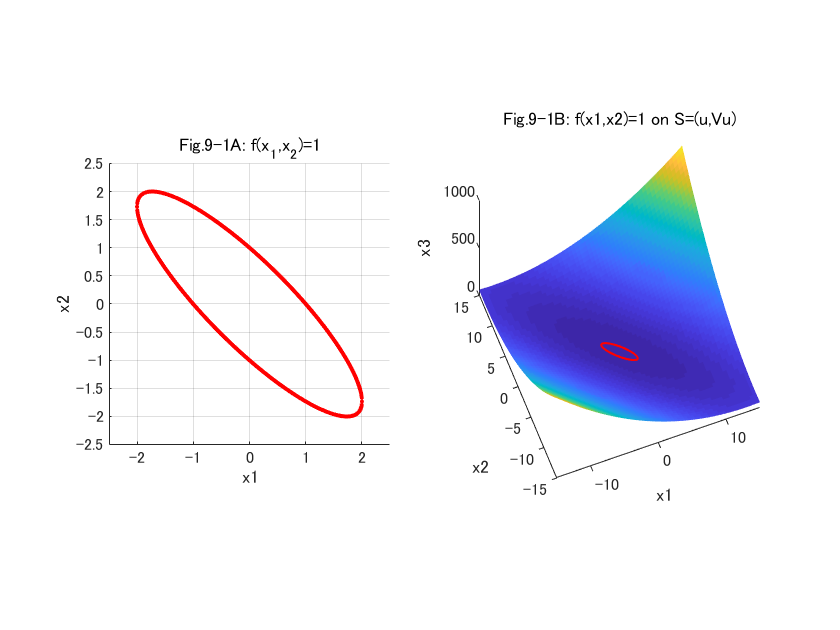

view([-21 64]);
axis([-15 15 -15 15 0 1000]);

左図は$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$のグラフです．関数$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$は長軸短軸が座標軸に対して斜めになった楕円であることがわかります．右図は${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$と$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$（赤）を示しています．すでに確認したように関数${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$のグラフはひしゃげたお椀のような形をしています．関数$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$が示すグラフはお椀を高さ${\mathrm{x}}_3 =1$で切断した断面であることが読み取れるかと思います．

## 標準形$S=\left(u\prime ,\mathit{Du}\prime \right)$と楕円の公式

次に，標準形$S=\left(u\prime ,\mathit{Du}\prime \right)$の場合を考えてみます．分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いると，$\mathrm{S}=\left(u,\mathit{Vu}\right)$は


$$\mathrm{S}=\left(u\prime ,\mathit{Du}\prime \right)$$


と変形することができました．いま，二変量データを考えているので，上式は


$$S=\lambda_1 {{\mathrm{u}}_1 \prime }^2 +\lambda_2 {{\mathrm{u}}_2 \prime }^2$$


と表すことができます．ここで，$u\prime =\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \prime \\
{\mathrm{u}}_2 \prime 
\end{array}\right\rbrack$および$V=\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$としました．ここで，


$$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\lambda_1 {{\mathrm{x}}_1 \prime }^2 +\lambda_1 {{\mathrm{x}}_2 \prime }^2$$


とすると，$\mathrm{S}=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは


$$\begin{array}{l}
{\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)\\
{{\mathrm{x}}_1 \prime }^2 +{{\mathrm{x}}_2 \prime }^2 =1
\end{array}$$


を満たす点ということになります．

さて，ここでも${{\mathrm{x}}_1 \prime }^2 +{{\mathrm{x}}_2 \prime }^2 =1$という条件式は無視して，


$$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$$


の式で表されるグラフを作成してみます．このグラフは${\mathrm{x}}_3 \prime =1$で示される平面における，${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$のグラフの切断面ととらえることができます．$D=\left\lbrack \begin{array}{cc}
1\ldotp 8601 & 0\\
0 & 0\ldotp 1338
\end{array}\right\rbrack$を当てはめると


$$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1\ldotp 8601{{\mathrm{x}}_1 \prime }^2 +0\ldotp 1338{{\mathrm{x}}_2 \prime }^2 =1$$


となり，そのグラフは以下のようになります．

figure('Name','Fig.9-3: g(x_1'',x_2'')=1');
subplot(1,2,1);
title('Fig.9-3A: g(x_1'',x_2'')=1'''); hold on;
% 1.8601x^2 + 0.1338y^2 = 1 % cf) WolframAlpha
t = linspace(-1/sqrt(1.8601), 1/sqrt(1.8601), 1000);
y1 = sqrt(10000-18601*t.^2) / sqrt(1338);
y2 = -sqrt(10000-18601*t.^2) / sqrt(1338);
ellip_xy = [repmat(t,1,2); y1 y2];
scatter(ellip_xy(1,:),ellip_xy(2,:),'r.');

xlabel('x1'''); ylabel('x2''');
axis([-3 3 -3 3]); axis square; grid on;
subplot(1,2,2);
title('Fig.9-3B: g(x1'',x2'')=1 on S=(u'',Du'')'); hold on;
[x1grid,x2grid] = meshgrid(-15:0.5:15, -15:0.5:15);
% z = 0.9970x^2+ 2*0.8632xy + 0.9770y^2; % cf. [https://www.wolframalpha.com/input/?i=z+%3D+0.9970x%5E2%2B+2*0.8632xy+%2B+0.9770y%5E2]
x3 = D(1,1)*x1grid.^2 + D(2,2)*x2grid.^2;
s = surf(x1grid,x2grid,x3);
xlabel('x1'''); ylabel('x2'''); zlabel('x3''');
s.EdgeColor = 'none'; axis square; hold on;
scatter3(ellip_xy(1,:),ellip_xy(2,:),ones(size(ellip_xy(1,:))),ones(size(ellip_xy(1,:)))*0.5,'r');

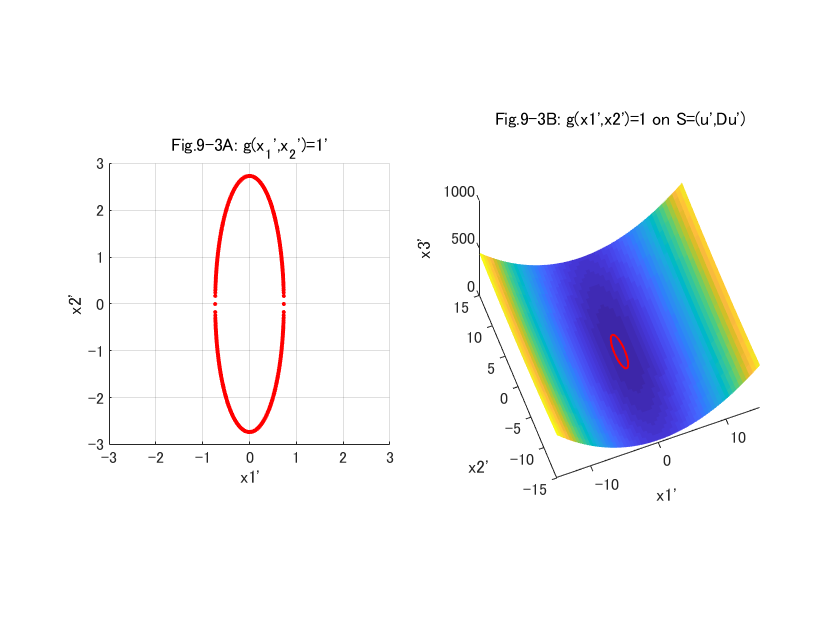

view([-21 64]);
axis([-15 15 -15 15 0 1000]);

左図は$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフで，右図は${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$と$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$（赤）を示しています．関数$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$は長軸短軸が座標軸と一致する楕円になっています．また，右図の${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$は，すでに確認したように関数${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$を回転させたものです．${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$のグラフと同様にひしゃげたお椀のような形をしていますが，勾配がもっとも大きい方向と横軸（${\mathrm{x}}_1 \prime$軸）が一致するようになっています．また，右図からは，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフが，${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$が示すお椀の形を高さ${\mathrm{x}}_3 \prime =1$で切断した断面であることが読み取れるかと思います．

### $g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$の図形的特徴

$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$の図形的な特徴について詳しく見ていきます．まずは，関数$1\ldotp 8601{{\mathrm{x}}_1 \prime }^2 +0\ldotp 1338{{\mathrm{x}}_2 \prime }^2 =1$を以下のように少しだけ書き換えます．


$$\frac{{{\mathrm{x}}_1 \prime }^2 }{{\left(1/\sqrt{1\ldotp 8601}\right)}^2 }+\frac{{{\mathrm{x}}_2 \prime }^2 }{{\left(1/\sqrt{0\ldotp 1338}\right)}^2 }=1$$


これは楕円の公式


$$\frac{{{\mathrm{x}}_1 \prime }^2 }{a^2 }+\frac{{{\mathrm{x}}_2 \prime }^2 }{b^2 }=1$$


の形式と一致します．つまり，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフは，${\mathrm{x}}_1 \prime$切片（${\mathrm{x}}_2 \prime =0$のときの${\mathrm{x}}_1 \prime$の値）が


$$\pm \frac{1}{\sqrt{1\ldotp 8601}}=\pm 0\ldotp 7332$$


また，${\mathrm{x}}_2 \prime$切片（${\mathrm{x}}_1 \prime =0$のときの${\mathrm{x}}_2 \prime$の値）が


$$\pm \frac{1}{\sqrt{0\ldotp 1338}}=\pm 2\ldotp 7338$$


の楕円として理解することができます．一般に，分散共分散行列$V$の固有値を$\lambda_1$および$\lambda_2$（$\lambda_1 >\lambda_2$）とすると，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$は


$$\frac{{{\mathrm{x}}_1 \prime }^2 }{{\left(1/\sqrt{\lambda_1 }\right)}^2 }+\frac{{{\mathrm{x}}_2 \prime }^2 }{{\left(1/\sqrt{\lambda_2 }\right)}^2 }=1$$


となり，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフは，${\mathrm{x}}_1 \prime$切片および${\mathrm{x}}_2 \prime$切片がそれぞれ$\pm 1/\sqrt{\lambda_1 }$，$\pm 1/\sqrt{\lambda_2 }$の楕円となります．これをグラフで確認すると以下のようになります．

figure('Name','Fig.9-4: intercepts of g(x_1'',x_2'')=1');
title('Fig.9-4: intercepts of g(x_1'',x_2'')=1'''); hold on;
% 1.8601x^2 + 0.1338y^2 = 1 % cf) WolframAlpha
t = linspace(-1/sqrt(1.8601), 1/sqrt(1.8601), 1000);
y1 = sqrt(10000-18601*t.^2) / sqrt(1338);
y2 = -sqrt(10000-18601*t.^2) / sqrt(1338);
ellip_xy = [repmat(t,1,2); y1 y2];
scatter(ellip_xy(1,:),ellip_xy(2,:),'r.');

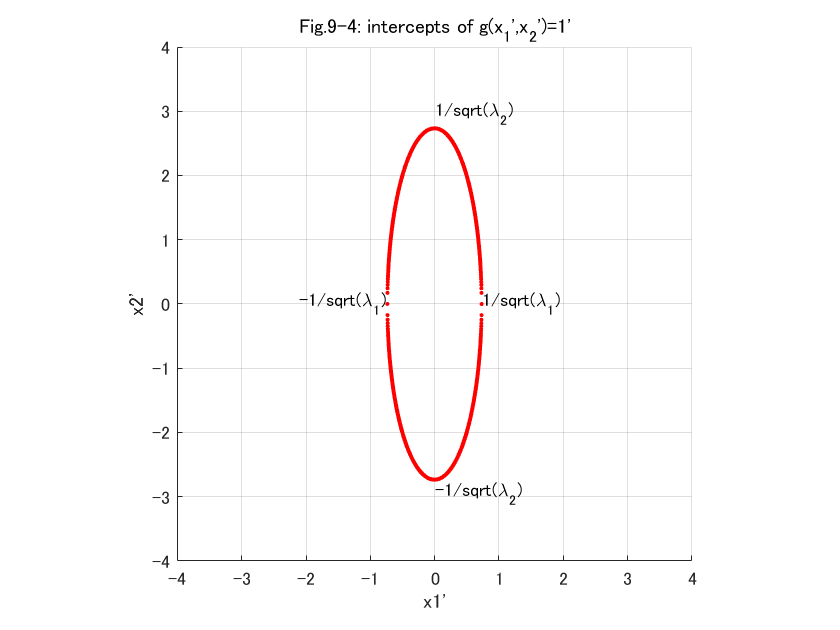

xlabel('x1'''); ylabel('x2''');
axis([-4 4 -4 4]); axis square; grid on;

text(1/sqrt(1.8601),0,'1/sqrt(\lambda_1)','HorizontalAlignment','left');
text(-1/sqrt(1.8601),0,'-1/sqrt(\lambda_1)','HorizontalAlignment','right');
text(0,1/sqrt(0.1338),0,'1/sqrt(\lambda_2)','HorizontalAlignment','left','VerticalAlignment','bottom');
text(0,-1/sqrt(0.1338),0,'-1/sqrt(\lambda_2)','HorizontalAlignment','left','VerticalAlignment','top');

図のように，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフは短軸長軸が座標軸に沿う楕円となります．その際，${\mathrm{x}}_1 \prime$切片および${\mathrm{x}}_2 \prime$切片がそれぞれ$\pm 1/\sqrt{\lambda_1 }$，$\pm 1/\sqrt{\lambda_2 }$となります．

## 標準化と楕円の回転

任意の方向における正射影ベクトルの長さの分散は


$$\mathrm{S}=\left(u,\mathit{Vu}\right)$$


という二次形式で表されます．分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いると，


$$\mathrm{S}=\left(u\prime ,\mathit{Du}\prime \right)$$


と標準化することができました（ただし，$u\prime =Q^T u$）．前章で確認したように，分散$S$の標準化は，グラフの回転としてとらえることができます．このとき，ベクトル$u$および$u\prime$が満たす関係


$$u\prime =Q^T u$$


はグラフの回転を表す関係式です．つまり，座標軸の回転に伴う座標変換の式としてとらえることができます．前述の二変量データの場合だと，座標系$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$から$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$への変換


$$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace \Longrightarrow^{Q^T } \left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$$


を表します．ここで，$e^{\left(1\right)} =\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$，$e^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$であり，$q^{\left(1\right)}$および$q^{\left(2\right)}$はそれぞれ行列$Q$の第一列および二列の縦ベクトルです．座標系$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$と$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$の関係は以下のように図式化できます．

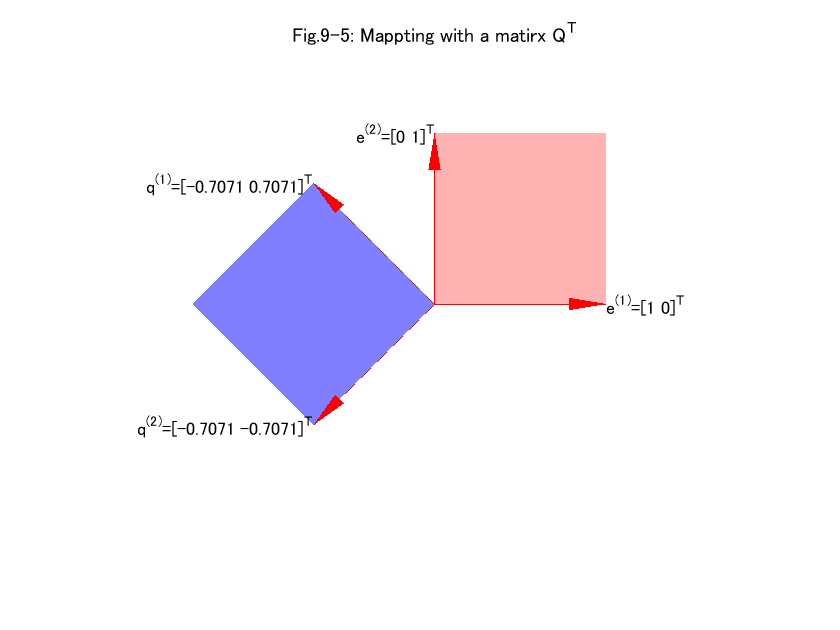

figure('Name','Fig.9-5: Mappting with a matirx Q''');
title('Fig.9-5: Mappting with a matirx Q^{T}')
x = [1; 0];
y = [0; 1];
xprime = Q'*x;
yprime = Q'*y;

patch([0 x(1) x(1)+y(1) y(1)],...
      [0 x(2) x(2)+y(2) y(2)],'red','FaceAlpha',0.3,'EdgeColor','none'); hold on;
patch([0 xprime(1) xprime(1)+yprime(1) yprime(1)],...
      [0 xprime(2) xprime(2)+yprime(2) yprime(2)],'blue','FaceAlpha',0.5,'EdgeColor','none');

axis([-1.5 1.5 -1.5 1.5]); axis square; axis off;
arrow3([0 0],x','r-'); text(x(1),x(2),'e^{(1)}=[1 0]^{T}','HorizontalAlignment','left');
arrow3([0 0],y','r-'); text(y(1),y(2),'e^{(2)}=[0 1]^{T}','HorizontalAlignment','right')
arrow3([0 0],xprime','r--');
str_xprime = sprintf('q^{(1)}=[%0.4f %0.4f]^{T}',xprime(1),xprime(2));
text(xprime(1),xprime(2),str_xprime,'HorizontalAlignment','right');
arrow3([0 0],yprime','r--');
str_yprime = sprintf('q^{(2)}=[%0.4f %0.4f]^{T}',yprime(1),yprime(2));
text(yprime(1),yprime(2),str_yprime,'HorizontalAlignment','right');

上図において，赤色の四角は正規直交基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$で囲まれる領域を示し，青色は正規直交基底$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$で囲まれる領域を示します．$u\prime =Q^T u$は赤色の領域から青色の領域に座標系を傾ける操作としてとらえることができます．

以下に，


$$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=0\ldotp 9970{{\mathrm{x}}_1 }^2 +2\times 0\ldotp 8632{\mathrm{x}}_1 {\mathrm{x}}_2 +0\ldotp 9970{{\mathrm{x}}_2 }^2 =1$$


で示される楕円と，その楕円を


$$\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack =Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$$


によって回転させた楕円を示します．

figure('Name','Fig.9-6: rotation with a matirix Q''');
subplot(1,2,1);
title('Fig.9-6A: Before rotation with a matirix Q^{T}'); hold on;
% 0.9970x^2 + 2*0.8632xy + 0.9970y^2 = 1 % cf) WolframAlpha
t = linspace(-2.00143, 2.00143, 1000);
y1 = (sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
y2 = (-sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
ellip_xy = [repmat(t,1,2); y1 y2];
scatter(ellip_xy(1,:),ellip_xy(2,:),'r.');

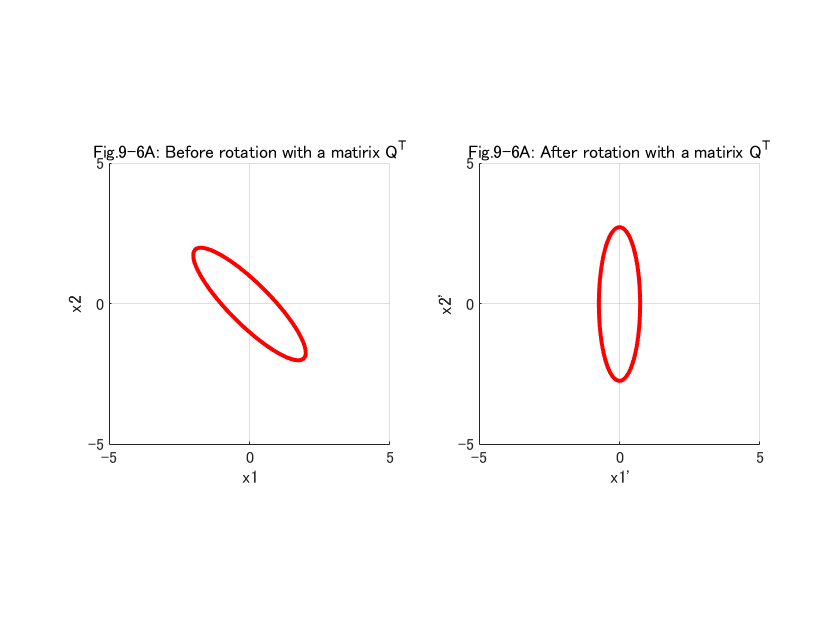

xlabel('x1'); ylabel('x2');
axis([-5 5 -5 5]); axis square; grid on;

subplot(1,2,2);
title('Fig.9-6A: After rotation with a matirix Q^{T}'); hold on;
xlabel('x1'''); ylabel('x2''');
axis([-5 5 -5 5]); axis square; grid on;
ellip_rot = Q'*ellip_xy;
scatter(ellip_rot(1,:),ellip_rot(2,:),'r.');

左は，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=0\ldotp 9970{{\mathrm{x}}_1 }^2 +2\times 0\ldotp 8632{\mathrm{x}}_1 {\mathrm{x}}_2 +0\ldotp 9970{{\mathrm{x}}_2 }^2 =1$で示される楕円です．右の図のは，左の楕円を


$$\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack =Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$$


によって回転させた楕円です．先ほどの正規直交基底の場合と同様に，$Q^T$によって回転している様子がわかります．その結果，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$で表される楕円となり，短軸が横軸（${\mathrm{x}}_1 \prime$軸）に，長軸が縦軸（${\mathrm{x}}_2 \prime$軸）に一致するようになっています．

## 楕円とデータの分布

ここまでは，楕円を$S=\left(u,\mathit{Vu}\right)$や$S=\left(u\prime ,\mathit{Du}\prime \right)$がが示すグラフを高さが$1$の平面で切断したときの楕円として説明してきました．ここでは，その楕円とデータの分布との関係を視覚化していきます．

### $f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$とデータの分布

まず，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$で表される楕円とデータの分布を比較してみます．

figure('Name','Fig.9-2: f(x_1,x_2)=1 with data plot');
subplot(1,2,1);
title('Fig.9-2A: f(x_1,x_2)=1 with data plot'); hold on;
% 0.9970x^2 + 2*0.8632xy + 0.9970y^2 = 1 % cf) WolframAlpha
t = linspace(-2.00143, 2.00143, 1000);
y1 = (sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
y2 = (-sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
ellip_xy = [repmat(t,1,2); y1 y2];
scatter(ellip_xy(1,:),ellip_xy(2,:),'r.');

xlabel('x1'); ylabel('x2');
axis([-15 15 -15 15]); axis square; grid on;
scatter(X(1,:),X(2,:),'g+');

subplot(1,2,2);
title('Fig.9-2B: f(x1,x2)=1 on S=(u,Vu) with data plot'); hold on;
[x1grid,x2grid] = meshgrid(-15:0.5:15, -15:0.5:15);
% z = 0.9970x^2+ 2*0.8632xy + 0.9770y^2; % cf. [https://www.wolframalpha.com/input/?i=z+%3D+0.9970x%5E2%2B+2*0.8632xy+%2B+0.9770y%5E2]
x3 = V(1,1)*x1grid.^2 + 2*V(1,2)*x1grid.*x2grid + V(2,2)*x2grid.^2;
s = surf(x1grid,x2grid,x3);
xlabel('x1'); ylabel('x2'); zlabel('x3');
s.EdgeColor = 'none'; axis square; hold on;
scatter3(ellip_xy(1,:),ellip_xy(2,:),ones(size(ellip_xy(1,:))),ones(size(ellip_xy(1,:)))*0.5,'r');

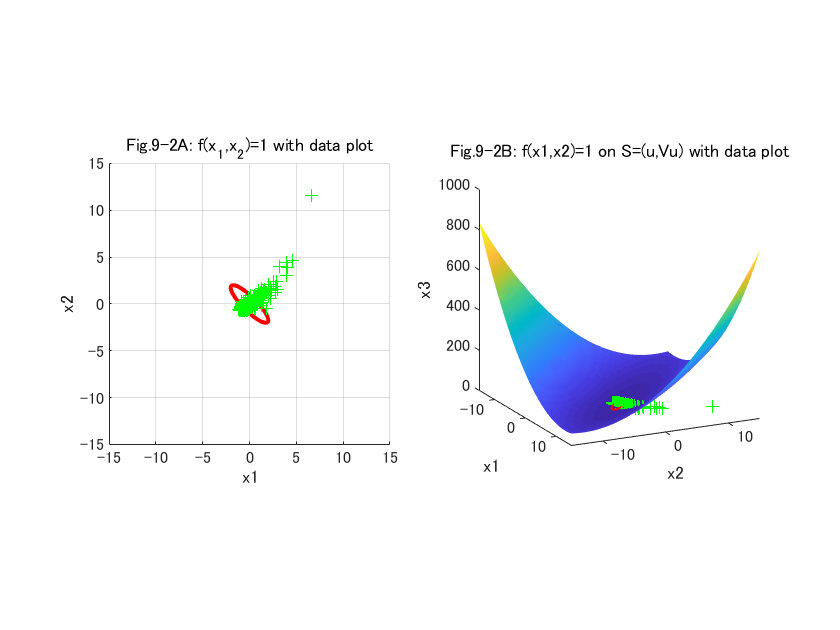

view([64 17]);
axis([-15 15 -15 15 0 1000]);
scatter3(X(1,:),X(2,:),ones(size(X(1,:))),'g+');

左図は$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$のグラフ（青）にデータの散布図（緑十字）を加えたものです．右図は${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$のグラフに$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$（赤）とデータの散布図（緑十字）を示しています．データの分布がもっとも広がっている方向が楕円の単軸になっているのがわかります．

### $g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$と主成分スコアの比較

つぎに，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$で表される楕円とデータの主成分スコアを比較してみます．$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$は，座標系を正規直交基底$\left\lbrace e^{\left(1\right)} ,e^{\left(2\right)} \right\rbrace$から$\left\lbrace q^{\left(1\right)} ,q^{\left(2\right)} \right\rbrace$に変換することで得られたものです．つまり，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$を


$$\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack =Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$$


によって座標変換して得られたものが$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$です．同様の変換をデータ行列$X$について適用したものが主成分スコアと考えることができます．すなわち，主成分スコアは


$$X\prime =Q^T X$$


として得ることができます．実際に計算してみると，

Xprime = Q'*X

Xprime =     0.9971   -0.6991    0.8441   -0.4020   -0.6753    0.8138    0.5227    0.4091    0.9723    0.6561   -0.9696    0.5348    0.8415    0.7120   -1.6036    0.8535    0.5510    0.2552    0.3492   -2.0879    0.7722   -0.1112   -0.1197   -0.0511    0.8336   -2.6862    0.4621    0.4294    0.6275    0.6082    0.5133    0.9484    0.9020   -1.9773    0.8597    0.9015    0.3624   -0.4798    0.5646    0.4727    0.5174    0.6332   -5.6264    0.0797    1.0577    0.7777    1.0391   -1.7565    0.5502    0.3653
   -0.3406   -0.0360    0.0436   -0.0562    0.2655    0.0443   -0.2736    0.0978   -0.0904   -0.0725    0.2138   -0.2896   -0.0126    0.1964    0.2607    0.0248    0.0537    0.2809   -0.4696    0.7451   -0.0015    0.7521   -0.0954   -0.6204   -0.2460    0.6643   -0.1100   -0.7603    0.2246   -0.1951    0.0554   -0.3851    0.0338    0.1028   -0.1368   -0.1485    0.1104    0.2340    0.0264   -0.1684   -0.0053   -0.3999    0.1761   -0.2357   -0.1447   -0.2766   -0.1956    0.1671    0.2531

となります．pca()関数によって求めた主成分係数は

scores'

ans =    -0.9971    0.6991   -0.8441    0.4020    0.6753   -0.8138   -0.5227   -0.4091   -0.9723   -0.6561    0.9696   -0.5348   -0.8415   -0.7120    1.6036   -0.8535   -0.5510   -0.2552   -0.3492    2.0879   -0.7722    0.1112    0.1197    0.0511   -0.8336    2.6862   -0.4621   -0.4294   -0.6275   -0.6082   -0.5133   -0.9484   -0.9020    1.9773   -0.8597   -0.9015   -0.3624    0.4798   -0.5646   -0.4727   -0.5174   -0.6332    5.6264   -0.0797   -1.0577   -0.7777   -1.0391    1.7565   -0.5502   -0.3653
    0.3406    0.0360   -0.0436    0.0562   -0.2655   -0.0443    0.2736   -0.0978    0.0904    0.0725   -0.2138    0.2896    0.0126   -0.1964   -0.2607   -0.0248   -0.0537   -0.2809    0.4696   -0.7451    0.0015   -0.7521    0.0954    0.6204    0.2460   -0.6643    0.1100    0.7603   -0.2246    0.1951   -0.0554    0.3851   -0.0338   -0.1028    0.1368    0.1485   -0.1104   -0.2340   -0.0264    0.1684    0.0053    0.3999   -0.1761    0.2357    0.1447    0.2766    0.1956   -0.1671   -0.2531   

となります．両者は互いに符合が反転しています．これは，eig()関数によって求めた行列$Q$とpca()関数によって求められた主成分係数の符号が反転しているためです．

Q

Q =    -0.7071    0.7071
   -0.7071   -0.7071


coefs

coefs =     0.7071   -0.7071
    0.7071    0.7071


いずれの行列の第一列もデータの分散$S=\left(u,\mathit{Vu}\right)$が最大となる方向（第一主成分）を示し，第二列目はそれと直交する方向（第二主成分）を示しています．分散$S=\left(u,\mathit{Vu}\right)$において，ベクトル$u$の方向のみが関係し，向き（符号）は関係ありません．そこでここでは，eig()関数によって得られた行列$Q$を採用して話を進めます．

以下に，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフと，$X\prime =Q^T X$によって得られた主成分スコアを示します．

figure('Name','Fig.9-5: g(x_1'',x_2'')=1 with pca scores');
subplot(1,2,1);
title('Fig.9-5A: g(x_1'',x_2'')=1'''); hold on;
% 1.8601x^2 + 0.1338y^2 = 1 % cf) WolframAlpha
t = linspace(-1/sqrt(1.8601), 1/sqrt(1.8601), 1000);
y1 = sqrt(10000-18601*t.^2) / sqrt(1338);
y2 = -sqrt(10000-18601*t.^2) / sqrt(1338);
ellip_xy = [repmat(t,1,2); y1 y2];
scatter(ellip_xy(1,:),ellip_xy(2,:),'r.');

xlabel('x1'''); ylabel('x2''');
axis([-15 15 -15 15]); axis square; grid on;
scatter3(Xprime(1,:),Xprime(2,:),ones(size(Xprime(1,:))),'g+');

subplot(1,2,2);
title('Fig.9-5B: g(x1'',x2'')=1 on S=(u'',Du'') with pca scores'); hold on;
[x1grid,x2grid] = meshgrid(-15:0.5:15, -15:0.5:15);
% z = 0.9970x^2+ 2*0.8632xy + 0.9770y^2; % cf. [https://www.wolframalpha.com/input/?i=z+%3D+0.9970x%5E2%2B+2*0.8632xy+%2B+0.9770y%5E2]
x3 = D(1,1)*x1grid.^2 + D(2,2)*x2grid.^2;
s = surf(x1grid,x2grid,x3);
xlabel('x1'''); ylabel('x2'''); zlabel('x3''');
s.EdgeColor = 'none'; axis square; hold on;
scatter3(ellip_xy(1,:),ellip_xy(2,:),ones(size(ellip_xy(1,:))),ones(size(ellip_xy(1,:)))*0.5,'r');

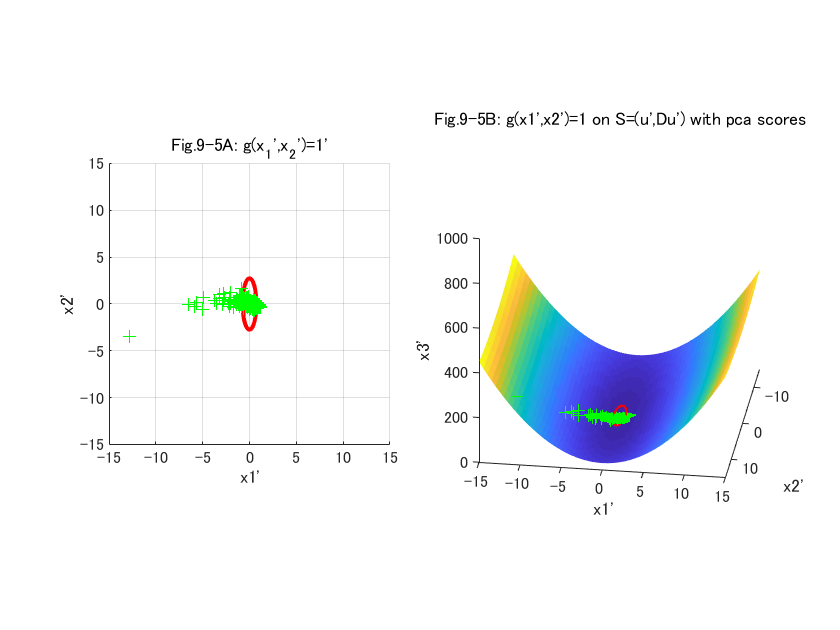

view([-8 -26]);
axis([-15 15 -15 15 0 1000]);
scatter3(Xprime(1,:),Xprime(2,:),ones(size(Xprime(1,:))),'g+');

左図は$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフ（赤）にデータの散布図（緑十字）を加えたものです．右図は${\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)$のグラフに$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$（赤）とデータの散布図（緑十字）を示しています．データの分布がもっとも広がっている方向が楕円の単軸になっているのがわかります．分散共分散行列$V$の固有値は対応する固有ベクトルが示す方向（主軸）における分散を示します．固有値分解$V=\mathit{QD}Q^T$を用いた二次形式$S=\left(u,\mathit{Vu}\right)$の標準化$S=\left(u\prime ,\mathit{Du}\prime \right)$は，分散が最大となる方向（第一主成分）が座標軸となるようにデータを回転させます．いまの場合，回転によって${\mathrm{x}}_1 \prime$軸においてデータの分散は最大となり，最大固有値となります．ここで，


$$\frac{{{\mathrm{x}}_1 \prime }^2 }{{\left(1/\sqrt{\lambda_1 }\right)}^2 }+\frac{{{\mathrm{x}}_2 \prime }^2 }{{\left(1/\sqrt{\lambda_2 }\right)}^2 }=1$$


より，${\mathrm{x}}_1 \prime$軸切片は固有値の平方根に反比例しますから，上式で表される楕円は最大固有値方向において単軸なります．また，最小固有値方向（${\mathrm{x}}_2 \prime$軸方向）が長軸となります．$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$のグラフは，短軸長軸が座標軸に沿うように$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$のグラフを回転させたものといえます．